# KNN and Random forest for classification

clc; clear;
close all;
warning off all;

Archivo data

archivo_csv = 'data.csv';
datos = readtable(archivo_csv);
disp(datos(1:10,:));

    tBodyAcc_mean___X    tBodyAcc_mean___Y    tBodyAcc_mean___Z    tBodyAcc_std___X    tBodyAcc_std___Y    tBodyAcc_std___Z    tBodyAcc_mad___X    tBodyAcc_mad___Y    tBodyAcc_mad___Z    tBodyAcc_max___X    tBodyAcc_max___Y    tBodyAcc_max___Z    tBodyAcc_min___X    tBodyAcc_min___Y    tBodyAcc_min___Z    tBodyAcc_sma__    tBodyAcc_energy___X    tBodyAcc_energy___Y    tBodyAcc_energy___Z    tBodyAcc_iqr___X    tBodyAcc_iqr___Y    tBodyAcc_iqr___Z    tBodyAcc_entropy___X    tBodyAcc_entropy___Y    tBodyAcc_entropy___Z    tBodyAcc_arCoeff___X_1    

datos = removevars(datos, 'subject');

Datos de Entrenamiento 70%

dataTrX = datos(1:2063,1:end-1);
dataTrY = datos(1:2063,end:end);
clases_unicas = table2cell(unique(dataTrY));

Datos de Testeo 30%

dataTeX = datos(2064:end,1:end-1);
dataTeY = datos(2064:end,end:end);

Entrenamiento KNN

[trainedClassifier1, validationAccuracy1] = KNN_train(datos, dataTrX, dataTrY, 'Euclidean', 100, 'Equal'); % No weighting
% validationAccuracy1
[trainedClassifier2, validationAccuracy2] = KNN_train(datos, dataTrX, dataTrY, 'Euclidean', 100, 'SquaredInverse'); % Weight is 1/distance^2
% validationAccuracy2
[trainedClassifier3, validationAccuracy3] = KNN_train(datos, dataTrX, dataTrY, 'Euclidean', 100, 'Inverse'); % Weight is 1/distance
% validationAccuracy3

Testeo y métricas KNN

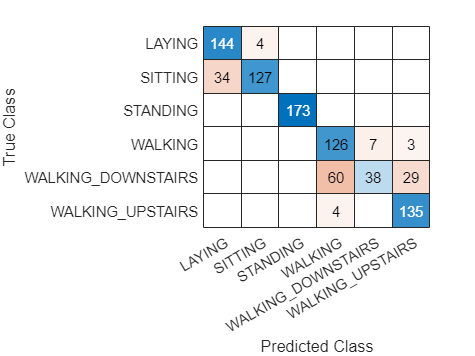

yfit1 = cellstr(trainedClassifier1.predictFcn(dataTeX));
matrizConfusion1 = confusionmat(table2cell(dataTeY), yfit1);
confusionchart(matrizConfusion1, clases_unicas);

Diagonal1 = diag(matrizConfusion1);

sum_rows1 = sum(matrizConfusion1,2);
sum_col1 = sum(matrizConfusion1,1);

Precision1 = mean(Diagonal1 ./ sum_rows1);
disp("Precision: " + Precision1);

Precision: 0.82645


Recall1 = mean(Diagonal1 ./ sum_col1');
disp("Recall: " + Recall1);

Recall: 0.84907


F1_Score1 = 2*((Precision1 * Recall1) / (Precision1 + Recall1));
disp("F1_Score: " + F1_Score1);

F1_Score: 0.83761


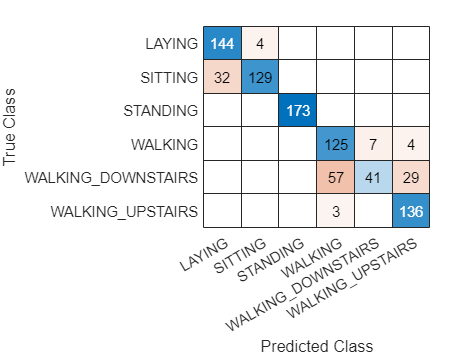



yfit2 = cellstr(trainedClassifier2.predictFcn(dataTeX));
matrizConfusion2 = confusionmat(table2cell(dataTeY), yfit2);
confusionchart(matrizConfusion2, clases_unicas);

Diagonal2 = diag(matrizConfusion2);

sum_rows2 = sum(matrizConfusion2,2);
sum_col2 = sum(matrizConfusion2,1);

Precision2 = mean(Diagonal2 ./ sum_rows2);
disp("Precision: " + Precision2);

Precision: 0.83243


Recall2 = mean(Diagonal2 ./ sum_col2');
disp("Recall: " + Recall2);

Recall: 0.85378


F1_Score2 = 2*((Precision2 * Recall2) / (Precision2 + Recall2));
disp("F1_Score: " + F1_Score2);

F1_Score: 0.84297


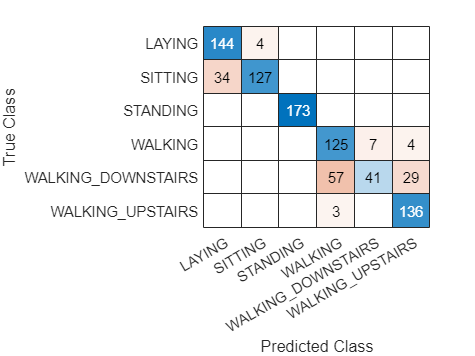


yfit3 = cellstr(trainedClassifier3.predictFcn(dataTeX));
matrizConfusion3 = confusionmat(table2cell(dataTeY), yfit3);
confusionchart(matrizConfusion3, clases_unicas);

Diagonal3 = diag(matrizConfusion3);

sum_rows3 = sum(matrizConfusion3,2);
sum_col3 = sum(matrizConfusion3,1);

Precision3 = mean(Diagonal3 ./ sum_rows3);
disp("Precision: " + Precision3);

Precision: 0.83036


Recall3 = mean(Diagonal3 ./ sum_col3');
disp("Recall: " + Recall3);

Recall: 0.85217


F1_Score3 = 2*((Precision3 * Recall3) / (Precision3 + Recall3));
disp("F1_Score: " + F1_Score3);

F1_Score: 0.84112


Visuaización consolidada por clases de métricas

modelosKNN = ["Equal"; "SquaredInverse"; "Inverse"];

res_precisionKNN = [Precision1, Precision2, Precision3];
res_recallKNN = [Recall1, Recall2, Recall3];
res_f1ScoreKNN = [F1_Score1, F1_Score2, F1_Score3];


resultadosKNN = table(modelosKNN, res_precisionKNN', res_recallKNN', res_f1ScoreKNN');
resultadosKNN.Properties.VariableNames = {'Modelos', 'Precision', 'Recall', 'F1-score'};

disp(resultadosKNN);

        Modelos         Precision    Recall     F1-score
    ________________    _________    _______    ________

    "Equal"              0.82645     0.84907    0.83761 
    "SquaredInverse"     0.83243     0.85378    0.84297 
    "Inverse"            0.83036     0.85217    0.84112 



Entrenamiento Random Forest

[trainedClassifier4, validationAccuracy4] = RandForest_train(datos, dataTrX, dataTrY, 11, 115);
%validationAccuracy4
[trainedClassifier5, validationAccuracy5] = RandForest_train(datos, dataTrX, dataTrY, 100, 30);
%validationAccuracy5

Testeo y métricas Random Forest

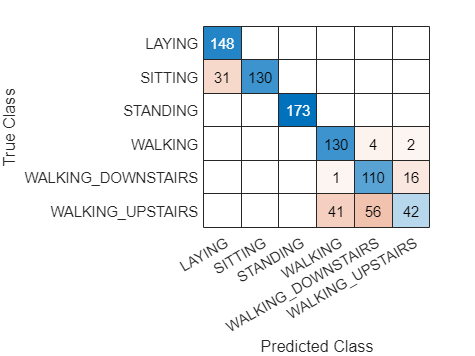

yfit4 = cellstr(trainedClassifier4.predictFcn(dataTeX));
matrizConfusion4 = confusionmat(table2cell(dataTeY), yfit4);
confusionchart(matrizConfusion4, clases_unicas);

Diagonal4 = diag(matrizConfusion4);

sum_rows4 = sum(matrizConfusion4,2);
sum_col4 = sum(matrizConfusion4,1);

Precision4 = mean(Diagonal4 ./ sum_rows4);
disp("Precision: " + Precision4);

Precision: 0.82194


Recall4 = mean(Diagonal4 ./ sum_col4');
disp("Recall: " + Recall4);

Recall: 0.82161


F1_Score4 = 2*((Precision4 * Recall4) / (Precision4 + Recall4));
disp("F1_Score: " + F1_Score4);

F1_Score: 0.82178


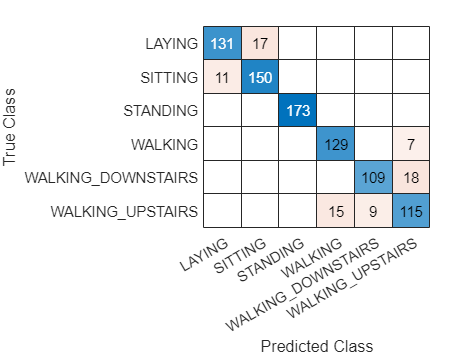



yfit5 = cellstr(trainedClassifier5.predictFcn(dataTeX));
matrizConfusion5 = confusionmat(table2cell(dataTeY), yfit5);
confusionchart(matrizConfusion5, clases_unicas);

Diagonal5 = diag(matrizConfusion5);

sum_rows5 = sum(matrizConfusion5,2);
sum_col5 = sum(matrizConfusion5,1);

Precision5 = mean(Diagonal5 ./ sum_rows5);
disp("Precision: " + Precision5);

Precision: 0.90849


Recall5 = mean(Diagonal5 ./ sum_col5');
disp("Recall: " + Recall5);

Recall: 0.91029


F1_Score5 = 2*((Precision5 * Recall5) / (Precision5 + Recall5));
disp("F1_Score: " + F1_Score5);

F1_Score: 0.90939


Visuaización consolidada por clases de métricas

modelosRandForest = ["[MaxNumSplits  = 11, NumLearningCycles  = 155]"; "[MaxNumSplits  = 100, NumLearningCycles  = 30]"];

res_precisionRandForest = [Precision4, Precision5];
res_recallRandForest = [Recall4, Recall5];
res_f1ScoreRandForest = [F1_Score4, F1_Score5];


resultadosRandForest = table(modelosRandForest, res_precisionRandForest', res_recallRandForest', res_f1ScoreRandForest');
resultadosRandForest.Properties.VariableNames = {'Modelos', 'Precision', 'Recall', 'F1-score'};

disp(resultadosRandForest);

                        Modelos                         Precision    Recall     F1-score
    ________________________________________________    _________    _______    ________

    "[MaxNumSplits  = 11, NumLearningCycles  = 155]"     0.82194     0.82161    0.82178 
    "[MaxNumSplits  = 100, NumLearningCycles  = 30]"     0.90849     0.91029    0.90939 

